# flutter

Solves dynamic stability of a 2-DoF airfoil in state-space description. Degrees of freedom are pitch ($\alpha$) and plunge ($h$) in Figure 3.1 below. The flap is not active ($\delta =0$). This is example 3.3 of Palacios & Cesnik's book.

Dependencies:

     **theodorsen_ajbj.m**: Coefficients of the RFA of Theodorsen's lift deficiency function.

Written by:

    Rafael Palacios (r.palacios@imperial.ac.uk)

Latest update:

     April 2024

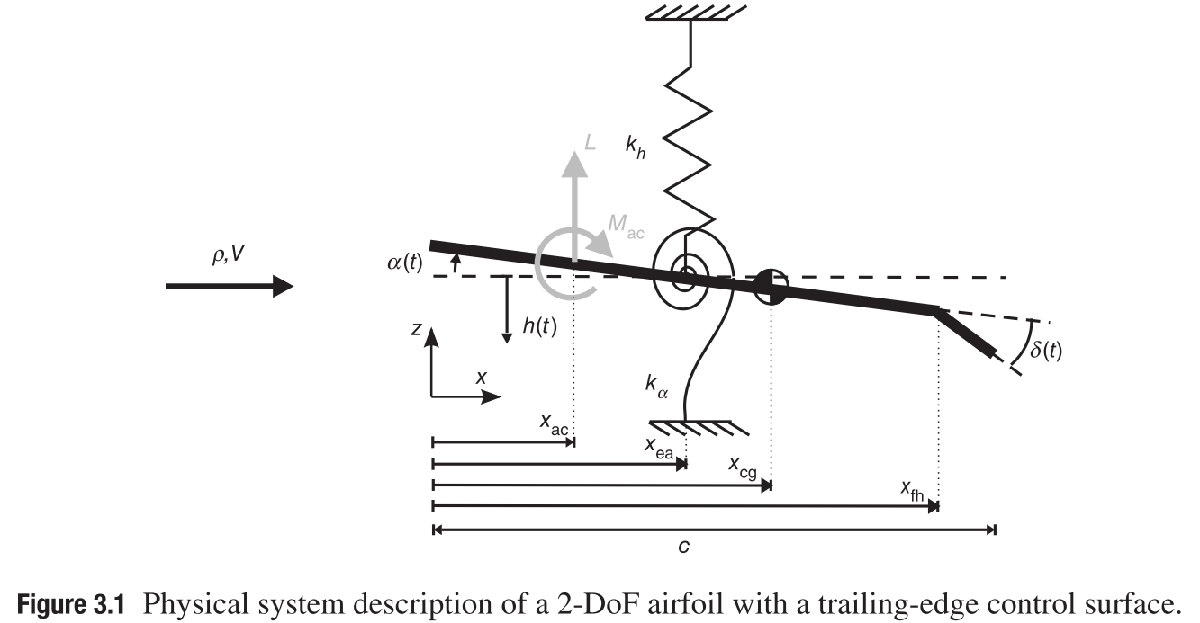

## Parameters

clear all

% Problem constants
rho=1; c=1; omega_a=1;     % Non-dim results are independent of this choice.
mu=5;                      % Mass ratio (m/(pi*rho*c^2)
r_a =0.25*c;               % Radius of gyration (sqrt(Ia/m))
x_ac=0.25*c;               % Coordinate of the aerodynamic centre
x_ea=0.35*c;               % Coordinate of the elastic axis

## Compute RFA

Obtain a rational-function approximation to the lift deficiency function, $\mathcal{C}\left(\textrm{ik}\right)=1-\sum_j \frac{\textrm{ik}\;a_j }{\textrm{ik}+b_j }$

Na=4;   % Order of the RFA.
a=zeros(1,Na);
b=zeros(1,Na);
[a,b]=theodorsen_ajbj(Na);

Plot RFA and the analytical function of C(ik)

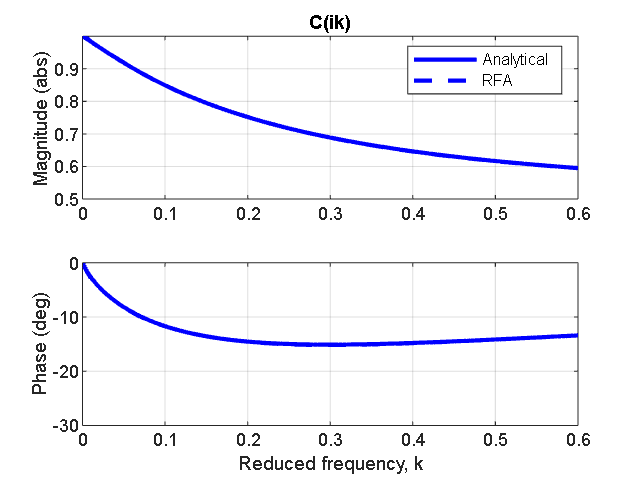

figure
k=0:0.005:0.6;
theo_rfa= @(xx) 1 - sum(kron(1i*xx,a)./( kron(ones(size(xx)),b) + kron(1i*xx,ones(size(b))) ),1);
subplot(2,1,1)
 plot(k,abs(theodorsen(k)),'b-', 'LineWidth',2), hold on
 plot(k,abs(theo_rfa(k)),'b--', 'LineWidth',2)
 ylabel('Magnitude (abs)'), title('C(ik)'), axis([0 max(k) 0.5  1]),  grid on, legend('Analytical','RFA')
subplot(2,1,2)
 plot(k,angle(theodorsen(k))*180/pi,'b-', 'LineWidth',2), hold on
 plot(k,angle(theo_rfa(k))*180/pi,'b--', 'LineWidth',2)
 xlabel('Reduced frequency, k'), ylabel('Phase (deg)'), axis([0 max(k) -30 0]), grid on

## Compute matrices for the aeroelastic model.

Default value for problem parameters.

omega_ratio= 0.5;    % Ratio of plunge/pitch typical frequencies
xalpha=0.1;          % Nondimensional position of cg (in semichords after the e.a.)

Define structural and inertial coefficients.

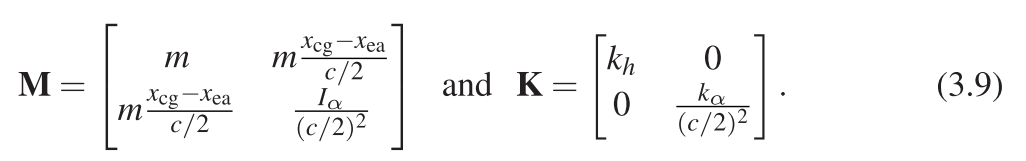

% Derived parameters:
    x_cg   = x_ea+xalpha*c/2;
    m      = mu*pi*rho*c^2;
    I_a    = m*r_a^2;
    k_a    = I_a*omega_a^2;
    omega_h= omega_ratio*omega_a;
    k_h    = m * omega_h^2;

% mass matrix and stiffness matrix:
    M=[[m m*(x_cg-x_ea)/(c/2)];[m*(x_cg-x_ea)/(c/2) I_a/(c^2/4)]];
    K=[[k_h 0];[0 k_a/(c^2/4)]];


Define aerodynamic constants for pitch/plunge airfoil:

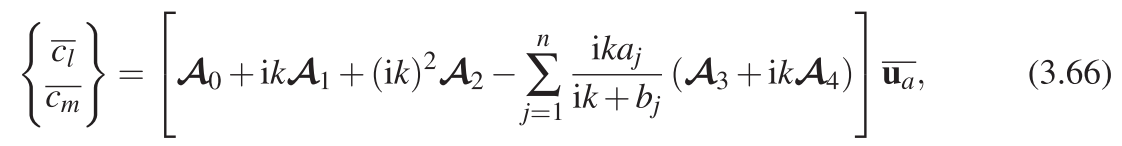

% Nondimensional axis of pitch rotation
    nu_ea  = (x_ea-c/2)/(c/2);

% Aerodynamics coefficients:
    CLa0qs=2*pi;
    CLa1qs=2*pi*(1/2-nu_ea);
    CMa1qs=-pi/4;
    CLa1nc=pi;
    CLa2nc=-pi*nu_ea;
    CMa1nc=-pi/4;
    CMa2nc=-pi/4*(1/4-nu_ea);

% Aerodynamics influence coefficient matrices:

    A_0 = [[0 CLa0qs];[0 0]];
    A_1 = [[CLa0qs CLa1qs+CLa1nc];[0 CMa1qs+CMa1nc]];
    A_2 = [[CLa1nc CLa2nc];[CMa1nc CMa2nc]];
    A_4 = [[CLa0qs CLa1qs];[0 0]];

% Matrix to map lift and moments to GAF for pitch and plunge.
    kappa_g=2*[[-1 0];[(x_ea-x_ac)/(c/2) 2]];

Create the state-space matrices for the aerodynamic lags

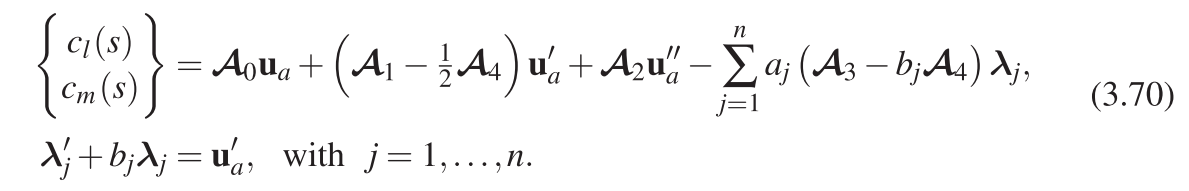

% State-space matrices for unsteady aero.
for j=1:Na
  A_a((j-1)*2+1:j*2,(j-1)*2+1:j*2)=-eye(2)*b(j);
  B_a((j-1)*2+1:j*2,1:2)=eye(2);
  C_a(1:2,(j-1)*2+1:j*2)= a(j)*(b(j)*A_4-A_0);
end

## Obtain V-g plots for given parameters

Loop through the airspeeds up the divergence speed. Compute the system matrix in non-dimensional time, and obtain the eigenvalues. In this case there are no gust inputs (i.e., $w_g =0$).

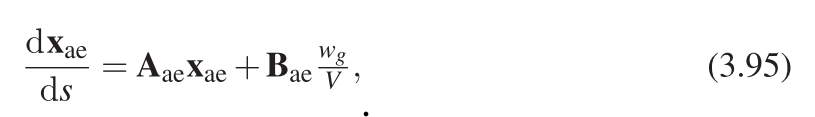

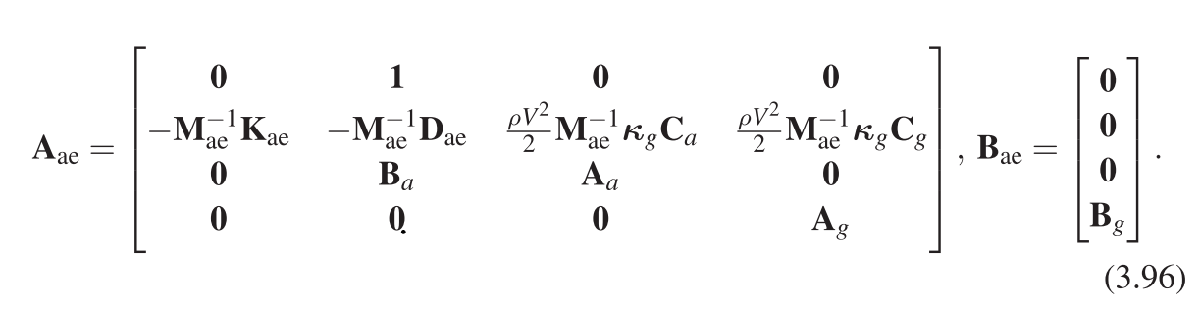

clear data
data.V=[0.005:0.005:1.77]; % Range of velocities to explore.
for kv=1:length(data.V)
   Vinf=data.V(kv);  
   qinf=1/2*rho*Vinf^2;

   % Compute aeroelastic inertia, damping and stiffness.
   M_ae=(4*Vinf^2/c^2)*M - qinf *kappa_g*A_2;
   D_ae=                 - qinf *kappa_g*(A_1-(1/2)*A_4);
   K_ae=               K - qinf *kappa_g*A_0;

   % Assemble the aeroelastic system matrix.
   A_ae=[[zeros(2)        eye(2)     zeros(2,2*Na)];
         [ -M_ae\K_ae    -M_ae\D_ae  M_ae\(qinf*kappa_g*C_a)];
         [zeros(2*Na,2)    B_a          A_a]];
   
   % Compute the dimensional eigenvalues.
   lambda=eig(A_ae)*(2*Vinf/c);

   data.lambda(kv,:)=lambda;   
end

Plot eigenvalues.

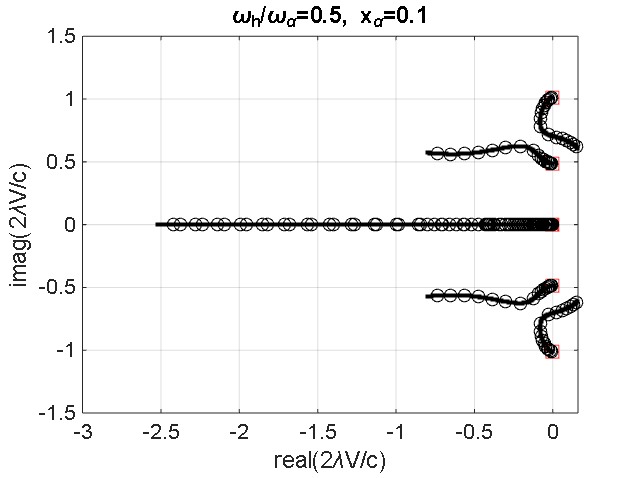

figure
plot(real(data.lambda),imag(data.lambda),'k.'), hold on
xlabel('real(2\lambdaV/c)'), ylabel('imag(2\lambdaV/c)'), grid on
title(['\omega_h/\omega_\alpha=' num2str(omega_ratio) ', x_\alpha=' num2str(xalpha)])

% Add big markers at V~Vmin and in increments of 0.1.
plot(real(data.lambda(1,:)),imag(data.lambda(1,:)),'rs','MarkerSize',8)
ii=floor(1/min(data.V))/10;
plot(real(data.lambda(ii:ii:end,:)),imag(data.lambda(ii:ii:end,:)),'ko')

V-g plot.

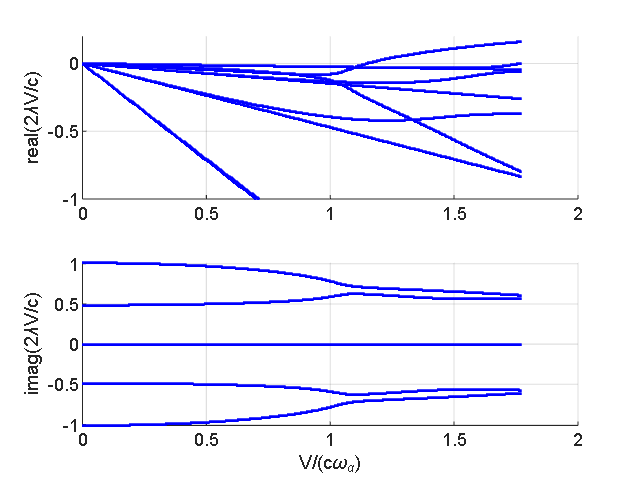

figure
subplot(2,1,1)
    ylabel('real(2\lambdaV/c)')
    grid on, hold on
subplot(2,1,2)
    xlabel('V/(c\omega_\alpha)')
    ylabel('imag(2\lambdaV/c)')
    grid on, hold on
for k=1:4+2*Na
    subplot(2,1,1), plot(data.V/(c*omega_a),real(data.lambda(:,k)),'b.','MarkerSize',4), axis([0 2 -1 0.2])
    subplot(2,1,2), plot(data.V/(c*omega_a),imag(data.lambda(:,k)),'b.','MarkerSize',4)
end

Finally, for a given velocity, we can look at the eigenvectors.

Vinf=0.1;  
qinf=1/2*rho*Vinf^2;

% Compute aeroelastic inertia, damping and stiffness.
M_ae=(4*Vinf^2/c^2)*M - qinf *kappa_g*A_2;
D_ae=                 - qinf *kappa_g*(A_1-(1/2)*A_4);
K_ae=               K - qinf *kappa_g*A_0;

% Assemble the aeroelastic system matrix.
A_ae=[[zeros(2)        eye(2)     zeros(2,2*Na)];
     [ -M_ae\K_ae    -M_ae\D_ae  M_ae\(qinf*kappa_g*C_a)];
     [zeros(2*Na,2)    B_a          A_a]];

% Compute the non-dimensional eigenvalues associated to the airfoil vibrations.
[eigvectors,eigvals]=eigs(A_ae,2,'largestimag');

% As a reference, use the natural vibrations of the structure.
[V1,V2]=eig(K,M);
sqrt(V2), eigvals*(2*Vinf/c)

ans =     0.4968         0
         0    1.0273


ans =   -0.0087 + 1.0100i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0058 + 0.4848i


for ii=1:2
    eigvectors(:,ii)=eigvectors(:,ii)/max(abs(eigvectors(:,ii)));
    V1(:,ii)=V1(:,ii)/max(abs(V1(:,ii)));
end
V1, eigvectors

V1 =    -1.0000   -0.1310
   -0.1310    1.0000


eigvectors =    0.0044 + 0.0277i   0.0049 + 0.4124i
  -0.0017 - 0.1980i  -0.0023 + 0.0595i
  -0.1400 + 0.0210i  -1.0000 + 0.0000i
   1.0000 + 0.0000i  -0.1441 - 0.0074i
   0.0043 + 0.0277i   0.0028 + 0.4125i
  -0.0012 - 0.1980i  -0.0026 + 0.0595i
   0.0040 + 0.0277i  -0.0076 + 0.4124i
   0.0012 - 0.1980i  -0.0041 + 0.0594i
   0.0031 + 0.0278i  -0.0349 + 0.4095i
   0.0075 - 0.1977i  -0.0081 + 0.0588i


## Loop through the parameters in the problem.

% Parametric variations:
omega_ratio=0.01:0.01:2;    % Ratio of plunge/pitch typical frequencies.
xalpha=[0 0.05 0.1 0.2];    % Nondimensional position of cg (semichords from x_ea).


for komega=1:length(omega_ratio)
for kxalpha=1:length(xalpha)
    omega_ratio(komega);

    % Derived parameters:
    x_cg = x_ea+xalpha(kxalpha)*c/2;
    m    = mu*pi*rho*c^2;
    I_a  = m*r_a^2;
    k_a  = I_a*omega_a^2;
    omega_h=omega_ratio(komega)*omega_a;
    k_h  = m * omega_h^2;
    nu_ea=(x_ea-c/2)/(c/2);

    % Aerodynamics influence coefficient matrices:
    CLa0qs=2*pi;
    CLa1qs=2*pi*(1/2-nu_ea);
    CMa1qs=-pi/4;
    CLa1nc=pi;
    CLa2nc=-pi*nu_ea;
    CMa1nc=-pi/4;
    CMa2nc=-pi/4*(1/4-nu_ea);
    
    A_0 = [[0 CLa0qs];[0 0]];
    A_1 = [[CLa0qs CLa1qs+CLa1nc];[0 CMa1qs+CMa1nc]];
    A_2 = [[CLa1nc CLa2nc];[CMa1nc CMa2nc]];
    A_4 = [[CLa0qs CLa1qs];[0 0]];
    
    % State-space matrices for unsteady aero.
    for j=1:Na
      A_a((j-1)*2+1:j*2,(j-1)*2+1:j*2)=-eye(2)*b(j);
      B_a((j-1)*2+1:j*2,1:2)=eye(2);
      C_a(1:2,(j-1)*2+1:j*2)= a(j)*(b(j)*A_4-A_0);
    end
      
   
    % Matrix of geometric coefficients for the generalized forces, 
    % mass matrix, and stiffness matrix:
    kappa_g=2*[[-1 0];[(x_ea-x_ac)/(c/2) 2]];
    M=[[m m*(x_cg-x_ea)/(c/2)];[m*(x_cg-x_ea)/(c/2) I_a/(c^2/4)]];
    K=[[k_h 0];[0 k_a/(c^2/4)]];
    
    
    % Loop through the vthrough the airspeeds up the diverspeed speed.
    Vinf=0.01;  Vmax=1.77; Vdelta=0.005;  % Range of velocities to explore.
    kv=0; Vflutter(kxalpha,komega)=1.78;
    while (Vinf<=Vmax) && (Vflutter(kxalpha,komega)==1.78)
       kv=kv+1;  
       qinf=1/2*rho*Vinf^2;

       M_ae=(4*Vinf^2/c^2)*M - qinf *kappa_g*A_2;
       C_ae=                 - qinf *kappa_g*(A_1-(1/2)*A_4);
       K_ae=               K - qinf *kappa_g*A_0;

       A_ae=[[zeros(2)        eye(2)     zeros(2,2*Na)];
             [ -M_ae\K_ae    -M_ae\C_ae  M_ae\(qinf*kappa_g*C_a)];
             [zeros(2*Na,2)    B_a          A_a]];
       
       % Compute dimensional eigenvalues:
       lambda=eig(A_ae)*(2*Vinf/c);
      
       % Check if there is a positive root.
       if max(real(lambda))>0
           Vflutter(kxalpha,komega)=Vinf;
       end
       Vinf=Vinf+Vdelta;
    end

end
end

Create flutter envelope plot.

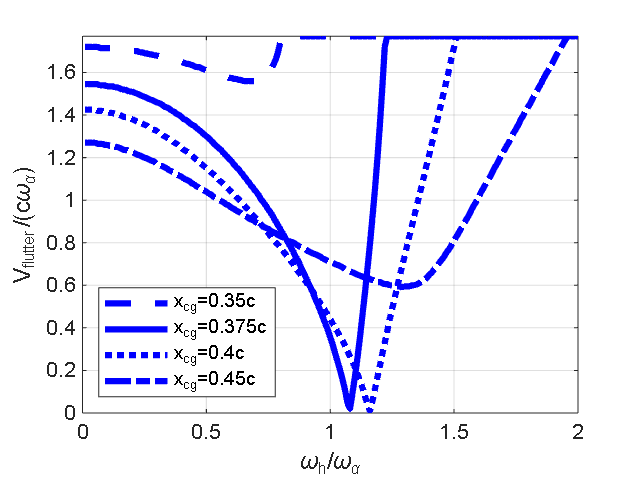

figure
plot(omega_ratio,Vflutter(1,:),'b--','LineWidth',3), hold on
plot(omega_ratio,Vflutter(2,:),'b-','LineWidth',3)
plot(omega_ratio,Vflutter(3,:),'b:','LineWidth',3)
plot(omega_ratio,Vflutter(4,:),'b-.','LineWidth',3)
axis([0 max(omega_ratio) 0 Vmax]), grid on
xlabel('\omega_h/\omega_\alpha'), ylabel('V_{flutter}/(c\omega_\alpha)')
legend(['x_{cg}=' num2str(x_ea+xalpha(1)/2) 'c'], ['x_{cg}=' num2str(x_ea+xalpha(2)/2) 'c'], ['x_{cg}=' num2str(x_ea+xalpha(3)/2) 'c'], ['x_{cg}=' num2str(x_ea+xalpha(4)/2) 'c'],'Location','southwest')